# Análisis de sensibilidad e incertidumbre usando matemática simbólica

## Preparación previa 

**1.** Definir los estados y los parámetros del modelo 

syms P(t) D(t)
syms alpha beta delta gamma

**2. **Se definen las ecuaciones 

ode1 = diff(P) == alpha*P - beta*P*D;
ode2 = diff(D) == delta*D*P - gamma*D;

odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}P\left(t\right)=\alpha \,P\left(t\right)-\beta \,\text{D}\left(t\right)\,P\left(t\right)\\ \frac{\partial }{\partial t}\text{D}\left(t\right)=\delta \,\text{D}\left(t\right)\,P\left(t\right)-\gamma \,\text{D}\left(t\right) \end{array}\right)$$

vars = [P D];

**3.** Definir el tiempo de simulación

domain = [0 30];
xdata = 0 : 0.1 : 30;

**4. **Utilizar la función gsua_dataprep para determinar orden de ingreso de los intervalos de los factores (parámetros y condiciones iniciales).

modelName = 'Lotka-Volterra';
gsua_dataprep(odes, vars, domain, modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$

**5.** Ingresar los intervalos de los factores de acuerdo al orden anteriormente mencionado

Ranges = [2 5;       %P(0)
          5 10;       %D(0)
          0.5 0.6;       %alpha
          0.2 0.3;       %beta
          0.2 0.3;       %delta 
          0.2 0.3        %gamma
          ];

**6.** Creación del objeto tipo tabla que se utilizará para hacer la estimación de parámetros 

[T, ~] = gsua_dataprep(odes, vars, domain, modelName, 'Range', Ranges);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccc} P\left(t\right) & \text{D}\left(t\right) & \alpha & \beta & \delta & \gamma \end{array}\right)$$

## Análisis de incertidumbre

**1. ** Definición de los conjuntos de parámetros a revisar (matriz M)

N = 100;  %número de simulaciones

**2.** Definir las salidas del modelo que se desean observar

T.Properties.CustomProperties.output = [1,2];

**3. **Correr el análisis de incertidumbre

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:15:17
Number of simulations: 100


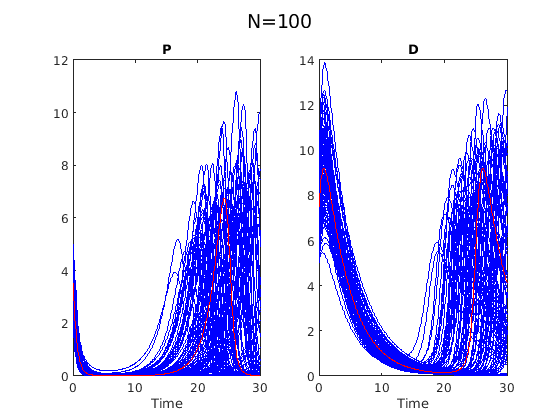

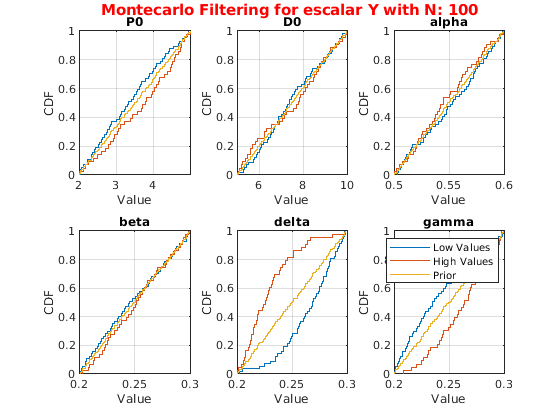

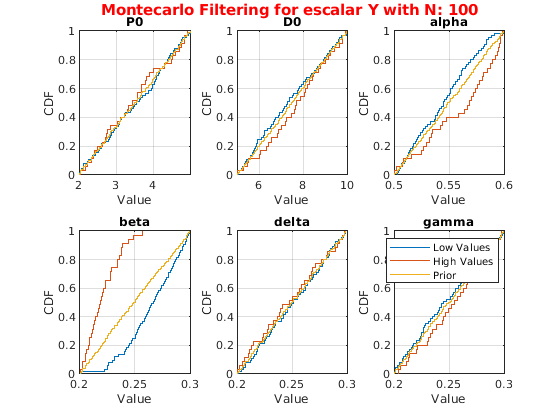

M = gsua_dmatrix(T, N, 'Method', 'Sobol');
gsua_ua(M, T, 'xdata', xdata,'parallel',false);

## Análisis de sensibilidad

**1. **Definir la salida que se desea observar

T.Properties.CustomProperties.output = 1;

**2. **Definición de los conjuntos de parámetros a revisar (matriz M)

N = 500; %número de simulaciones
M = gsua_dmatrix(T, N, 'Method', 'Sobol');

**3.** Correr análisis de sensibilidad

T = gsua_sa(M, T, 'SensMethod', 'Xiao', 'xdata', xdata);

Progress: 13%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:2
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:15:27
Number of simulations: 2000
Progress: 25%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:15:26
Number of simulations: 2000
Progress: 38%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:15:26
Number of simulations: 2000
Progress: 50%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:15:26
Number of simulations: 2000
Progress: 63%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:15:26
Number of simulations: 2000
Progress: 75%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s)

**4.** Identificar si se realizaron suficientes simulaciones para el análisis de sensibilidad (el valor debe ser cercano a 1 para tener un resultado confiable). 

sum(T.Si)/sum(abs(T.Si))

ans = 0.9566

**5. **Graficar los indices de sensibilidad para analizar el resultado

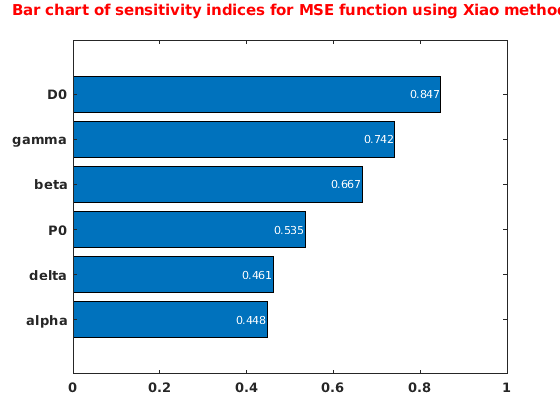

figure
gsua_plot('Bar', T, T.STi)

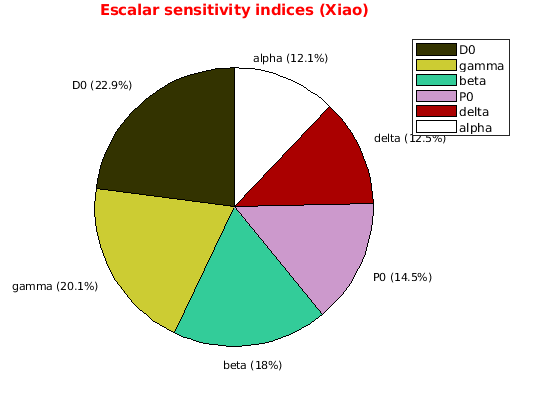

figure
gsua_plot('Pie',T, T.STi)

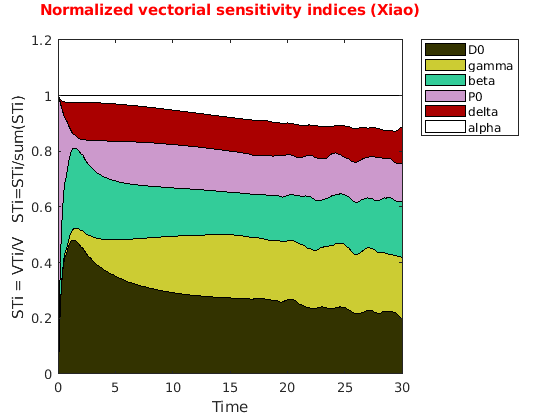

figure
gsua_plot('TotalSensitivityArea', T, T.STi_vec, xdata);